# Conducting IQC analysis

A fundamental value of `iqcToolbox` is its ability to leverage integral quadratic constraints (IQCs) to conduct worst-case stability/performance analysis on uncertain and nonlinear systems. This type of analysis is called IQC analysis. After this script, you will gain a superficial understanding of the concepts behind IQC analysis and a concrete understanding of how you can conduct IQC analysis with the commands from `iqcToolbox`.

## Brief theoretical background and why it's important

The central object of analysis in `iqcToolbox` is a linear fractional transformation (LFT) of an uncertain and nonlinear system $(M,\Delta)$, which describes a mapping from disturbance input signals $d$ to output signals $e$ (see equations and block diagram below).


$$\qquad \quad \matrix{ \phi & = & \Delta(\theta) \cr
     \theta & = & M_{11} \phi + M_{12} d \cr
     e & = & M_{21} \phi + M_{22} d}$$


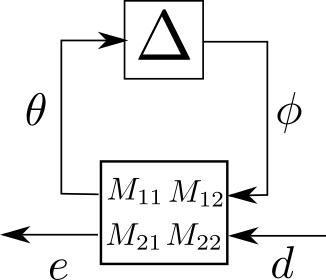

More information on LFTs can be found in the section "Modeling uncertain systems with the Ulft class". 

IQC analysis allows one to characterize the effects of uncertain, troublesome, or complicated elements ($\Delta \in \Delta_{\mbox{set}}
$ and $d \in \mathcal{D}$) on the nominal, linear system $M$ and its output $e$, according to a predefined performance metric $\mathcal{P}$. Using the common "$\ell_2$-induced" performance metric with a performance level $\gamma$, conducting IQC analysis results in determining if the LFT $(M, \Delta)$ is robustly stable, and if


$$(1) \qquad||e||_{\ell_2} < \gamma ||d||_{\ell_2}, \mbox{ where } e = (M, \Delta)(d), \ \Delta \in \Delta_\mbox{set}, \ d \in \mathcal{D} \subseteq \ell_2$$


(i.e., the system has a robust $\mathcal{D}$-to-$\ell_2$-induced performance level of $\gamma$) . IQC analysis represents worst-case analysis, meaning that it produces (if feasible) the tightest upper bound $\gamma$ on how much any admissible disturbance may "affect" the output of any system sampled from the set of uncertain systems.

Characterizing the performance metric $\mathcal{P}$, the set of admissible uncertainties/nonlinearites $\Delta_\mbox{set}$, and the set of admissible disturbances $\mathcal{D}$ is done with so-called IQC multipliers $\Pi_P$, $\Pi_\Delta$, and $\Pi_D$, which are linear, self-adjoint operators that (in this toolbox) have state-space expresssions. To generalize (1), we consider a generic performance metric characterized by the performance multiplier $\Pi_P$ and say that $(M, \Delta)$ has a robust $\mathcal{D}$-$\mathcal{P}$ performance if $(M,\Delta)$ is robustly stable and if

 
$$(2) \qquad \langle \left[\matrix{e \cr d}\right], \Pi_P \left[\matrix{e \cr d}\right]\rangle < 0\mbox{ where } e = (M, \Delta)(d), \ \Delta \in \Delta_\mbox{set}, \ d \in \mathcal{D} \subseteq \ell_2$$


with $\langle \cdot, \cdot \rangle$denoting the inner-product over $\ell_2$. Note, equation (1) can be recovered from equation (2) by defining $\Pi_P = \left[\matrix{I & 0 \cr 0 & -\gamma^2 I}\right]$.

IQC multipliers $\Pi_P$, $\Pi_\Delta$, $\Pi_D$ are composed of basis functions and decision variables that must satisfy constraints according to the properties of $\mathcal{P}$, $\Delta_\mbox{set}$, and $\mathcal{D}$.  IQC analysis amounts to defining the appropriate constraints on $\Pi_P$, $\Pi_\Delta$, $\Pi_D$, and using $M$, $\Pi_P$, $\Pi_\Delta$, and $\Pi_D$ to formulate and solve a semidefinite program.  If a feasible solution exists, then (2) holds.  If not, then we can make no robustness conclusions.

Importantly, the default structure and complexity of each class of IQC multipliers is already defined in `iqcToolbox`. However, users can provide simpler or richer expressions of each utilized IQC multiplier when conducting IQC analysis. This capability helps users find a balance between the expressiveness of the constraints and the tractability of the semidefinite program.

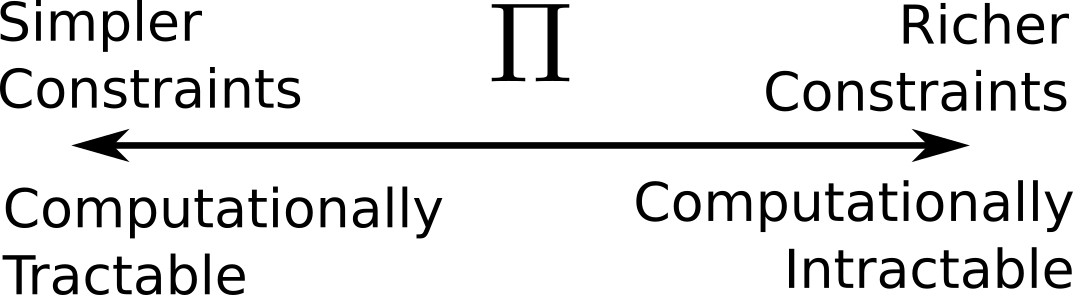

Finding the right balance oftentimes matters, because semidefinite programs tend to produce worse results on the border of "computationally intractable" problems.  Hence, users may find that simpler constraints not only reduce solution times, but sometimes may also reduce the conservatism of the results themselves.

## Basic IQC analysis

Consider the example first introduced in the "Getting started" documentation:


$$G_\delta: \quad \quad \matrix{ 
x(k+1) & = & \left[\matrix{ 0 & 3/4 + \delta \cr 3/4 - \delta & 0}\right] & x(k)& + & \left[\matrix{1 \cr 0}\right] & u(k) \cr
y(k) & = & \left[\matrix{1\quad& 0}\right] & x(k)}$$



$$\mbox{ where } \delta \in [-1/2, 1/2]$$


dims = 1;
lower_bound = -1/2;
upper_bound = 1/2;
% a 1x1 Static, Linear, Time-Invariant (SLTI) uncertainty with the given bounds
del = DeltaSlti('del', dims, lower_bound, upper_bound)  
a_del = [0, 3/4 + del; 3/4 - del, 0];   % the uncertain A-matrix 
b = [1; 0];
c = [1, 0];
d = 0;
timestep = -1;   % An unspecified timestep
g_del = toLft(a_del, b, c, d, timestep) % the uncertain system defined with the uncertain A-matrix

As discussed in the "Modeling uncertain systems with the Ulft class" documentation, a `Ulft` object expresses the nominal portion of the system (`a`, `b`, `c`, `d`), the uncertainties (`delta`), the performance (`performance`), and the disturbances (`disturbance`), which is enough information to directly call `iqcAnalysis`.

result = iqcAnalysis(g_del)

Calling `iqcAnalysis` with this single argument will likely constitute a large majority of a user's invocation of the function. However, `iqcAnalysis` has numerous additional arguments that can be included to provide users more flexibility.

## Additional input arguments to `iqcAnalysis`

`iqcAnalysis` may be called with up to four additional key/value pair arguments:

options = AnalysisOptions();                                             % To be defined later
m_del(2) = MultiplierSlti(g_del.delta.deltas{2});                        % To be defined later
m_perf = MultiplierL2Induced(g_del.performance.performances{1},...
                             size(g_del, 1),...
                             size(g_del, 2));                            % To be defined later
m_dis = MultiplierL2(g_del.disturbance.disturbances{1}, size(g_del, 2)); % To be defined later
result = iqcAnalysis(g_del,...
                     'analysis_options', options,...
                     'multipliers_delta', m_del,...
                     'multipliers_performance', m_perf,...
                     'multipliers_disturbance', m_dis)         

The next sections describe each input argument in detail.

### `analysis_options`

This input argument allows users to express options in the analysis routine that affect the IQC analysis problem universally (rather  than particularly on a single uncertainty, disturbance, or performance). The input must be an `AnalysisOptions` object, which (as of v0.9.0) has 3 different types of parameters: semidefinite solver parameters, parameters describing the initial conditions of $(M, \Delta)$, and an exponential IQC parameter. We will discuss the first two types here; a discussion on the exponential IQC parameter is found in-depth in the "Exponential IQCs" documentation. 

#### Semidefinite solver parameters

`lmi_shift`, `solver`, `verbose`, and `debug` are four parameters that pertain to how the semidefinite program is parsed. Their default values are the input arguments below:

options = AnalysisOptions('lmi_shift', 1e-8, 'solver', 'SDPT3', 'verbose', true, 'debug', false);

The `lmi_shift` parameter prescribes how strict inequalities are enforced in the semidefinite constraints:


$$X\succ 0 \Rightarrow X\succeq (\texttt{lmi\_shift} )I$$


In some cases, `iqcAnalysis` may provide a result which is invalid (i.e., `result.valid == false && result.performance == Inf`), even though the solver reports that an optimal solution was found. This is usually because semidefinite solvers sometimes produce a solution that barely violates constraints. Users can address this issue by specifying `lmi_shift` to be slightly larger, such that the obtained solution still remains positive or negative definite. However, increasing `lmi_shift` too much may lead to overly conservative or infeasible problems. Unfortunately, this issue arises differently in different machines, so users may need to adapt `lmi_shift` on different platforms and problems.

The `solver` parameter may be any solver installed on your machine (SPDT3 is open-source and the only solver installed with `iqcToolbox`). The remaining parameters are self-explanatory.

#### Uncertain initial conditions

IQC analysis can also incorporate the effect of uncertain initial conditions on the system's worst-case performance.  If $(M,\Delta)$ has an internal state, and the initial state resides in an ellipse centered about zero:


$$x_M(0) \in E(\Xi) = \{x \in \mathbb{R}^n | x^T \Xi x \leq 1\}$$


where $\Xi\succ 0$, then IQC analysis can measure the robust $({E(\Xi),\mathcal{D})\mbox{-to-}\ell_2$-induced performance level $(\gamma, \lambda)$, which guarantees that:


$$(3) \qquad \langle \left[\matrix{e \cr d}\right], \Pi_P \left[\matrix{e \cr d}\right]\rangle < \lambda^2\mbox{ where } e = (M^{ic}, \Delta)(d), \ \Delta \in \Delta_\mbox{set}, \ d \in \mathcal{D} \subseteq \ell_2,  \ x_M(0) \in E(\Xi)$$


If using the typical $\ell_2$-induced performance metric, (3) becomes


$$(4) \qquad ||e||^2_{\ell_2} < \gamma^2 ||d||^2_{\ell_2} + \lambda^2\mbox{ where } e = (M^{ic}, \Delta)(d), \ \Delta \in \Delta_\mbox{set}, \ d \in \mathcal{D} \subseteq \ell_2, \ x_M(0) \in E(\Xi)$$


The ellipse of uncertain initial conditions is specified in `iqcToolbox` with parameters in the `analysis_options` variable.  For example, consider the previous system with initial conditions that could be anywhere in the unit ball:


$$G^{ic}_\delta: \quad \quad \matrix{ 
x(k+1) & = & \left[\matrix{ 0 & 3/4 + \delta \cr 3/4 - \delta & 0}\right] & x(k)& + & \left[\matrix{1 \cr 0}\right] & u(k), \qquad ||x(0)|| \leq 1 \cr
y(k) & = & \left[\matrix{1\quad& 0}\right] & x(k)}$$



$$\mbox{ where } \delta \in [-1/2, 1/2]$$


Analysis of this system is accomplished by specifying the ellipse in  `analysis_options` and calling `iqcAnalysis`:

e_mat = eye(2); % Ellipse specified as {x in R^n | x' * e_mat * x <= 1}
uncertain_states = [true, true];
options = AnalysisOptions('init_cond_ellipse', e_mat,'init_cond_states', uncertain_states);
result_ic = iqcAnalysis(g_del, 'analysis_options', options)

The key/value pair `{'init_cond_ellipse', e_mat}` specifies $\Xi$ in the ellipse description $E(\Xi) = \{x \in \mathbb{R}^n | x^T \Xi x \leq 0\}$

The key/value pair `{'init_cond_states', uncertain_states}` indicates which states are uncertain. In the previous case, both are.  However, consider the scenario where only one state is uncertain:


$$G^{ic}_\delta: \quad \quad \matrix{ 
x(k+1) & = & \left[\matrix{ 0 & 3/4 + \delta \cr 3/4 - \delta & 0}\right] & x(k)& + & \left[\matrix{1 \cr 0}\right] & u(k), \qquad -1 \leq x_1(0)  \leq 1 \cr
y(k) & = & \left[\matrix{1\quad& 0}\right] & x(k)}$$



$$\mbox{ where } \delta \in [-1/2, 1/2]$$


This would require `e_mat` and `uncertain_states` to change: 

e_mat = 1;
uncertain_states = [true, false]
options = AnalysisOptions('init_cond_ellipse', e_mat,'init_cond_states', uncertain_states);
result_ic = iqcAnalysis(g_del, 'analysis_options', options)

If, instead, we wanted to specify $-3 \leq x_2(0) \leq 3$:

e_mat = 1 / 3 ^ 2;
uncertain_states = [false, true]
options = AnalysisOptions('init_cond_ellipse', e_mat,'init_cond_states', uncertain_states);
result_ic = iqcAnalysis(g_del, 'analysis_options', options)

We can see that incorporating uncertain initial conditions increases the `performance` level:

[result.performance result_ic.performance] % [x0 == 0, x0 in ellipse]

and produces a new variable `state_amplification`, which represents $\lambda$ in Eqns (3) and (4):

[result.state_amplification, result_ic.state_amplification] % [x0 == 0, x0 in ellipse]

Because we have introduced uncertainty in the initial conditions, IQC analysis is no longer optimizing just one variable (`result_ic.performance`, or in other words, $\gamma$), but two variables `(result_ic.state_amplification`, or in other words, $\lambda$). This vector optimization problem must be scalarized, and the weighting on the state amplification objective is expressed with the input option `scale_state_obj:`

% optimize(result.performance + options.scale_state_obj * result.state_amplification)

If we set this weighting to zero, IQC analysis will return a very large `state_amplification` value:

options = AnalysisOptions('scale_state_obj', 0,...
                          'init_cond_ellipse', e_mat,...
                          'init_cond_states', uncertain_states);
result_ic = iqcAnalysis(g_del, 'analysis_options', options);
result_ic.state_amplification

If instead `scale_state_obj` were high, we would get a much smaller `state_amplification` value:

options = AnalysisOptions('scale_state_obj', 1e4,...
                          'init_cond_ellipse', e_mat,...
                          'init_cond_states', uncertain_states);
result_ic = iqcAnalysis(g_del, 'analysis_options', options);
result_ic.state_amplification

The last option that is associated with uncertain initial conditions is `p0`. This is largely for debugging purposes, and allows users to specify an explicit solution matrix which, among other conditions, must satisfy $P_0 \leq \Xi$.

### Specifying IQC multipliers

In addition to `analysis_options`, users may specify the properties of specific multipliers for specific uncertainties, disturbances, and performances.  This enables a tailored balancing of conservativeness and computational complexity.  These multipliers are broken into three different types of arrays: `multipliers_delta`, `multipliers_disturbance`, and `multipliers_performance`. If a multiplier is not specified, the default parameters for that multiplier are used instead.

The remainder of this section will use the following `analysis_options`

options = AnalysisOptions('lmi_shift', 1e-7, 'solver', 'sdpt3');

#### `multipliers_delta`

This array of multipliers pertains to each `Delta` object in a `Ulft`. Consider the system:


$$G_\delta: \quad \quad \matrix{ 
x(k+1) & = & \left[\matrix{ \delta_{tv}(k) & 3/4 + \delta_{ti} \cr 3/4 - \delta_{ti} & 0}\right] & x(k)& + & \left[\matrix{1 \cr 0}\right] & u(k) \cr
y(k) & = & \left[\matrix{1\quad& 0}\right] & x(k)}$$



$$\mbox{ where } \delta_{tv}(k) \in [-1/4,  \ 1/4] \mbox{ and } \delta_{ti} \in [-1/2, \ 1/2]$$


del_tv = DeltaSltv('del_tv', dims, -1/4, 1/4); % Time-varying uncertainty
del_ti = DeltaSlti('del_ti', dims, -1/2, 1/2); % Time-invariant uncertainty
a_dels = [del_tv,       3/4 + del_ti;
          3/4 - del_ti,          0];
g_dels = toLft(a_dels, b, c, d, timestep)

we could specify an explicit multiplier for `del_ti`, the `DeltaSlti` object:

mult_slti = MultiplierSlti(g_dels.delta.deltas{3})
mults_del(3) = mult_slti
results = iqcAnalysis(g_dels, 'multipliers_delta', mults_del, 'analysis_options', options)

The previous lines of code are actually no different than simply calling `iqcAnalysis(g_dels)`, because we constructed `mult_slti` from `del_ti` without any additional input parameters. However, we could specify a richer set of multipliers describing `del_ti`:

mult_slti = MultiplierSlti(g_dels.delta.deltas{3},'basis_length', 3)
mults_del(3) = mult_slti;
results = iqcAnalysis(g_dels, 'multipliers_delta', mults_del, 'analysis_options', options)

Multipliers are specified for each `Delta` object by ordering the array of `MultiplierDelta` objects in correspondence with the array of `Delta` objects in a specific `Ulft`. For the previous example, we see:

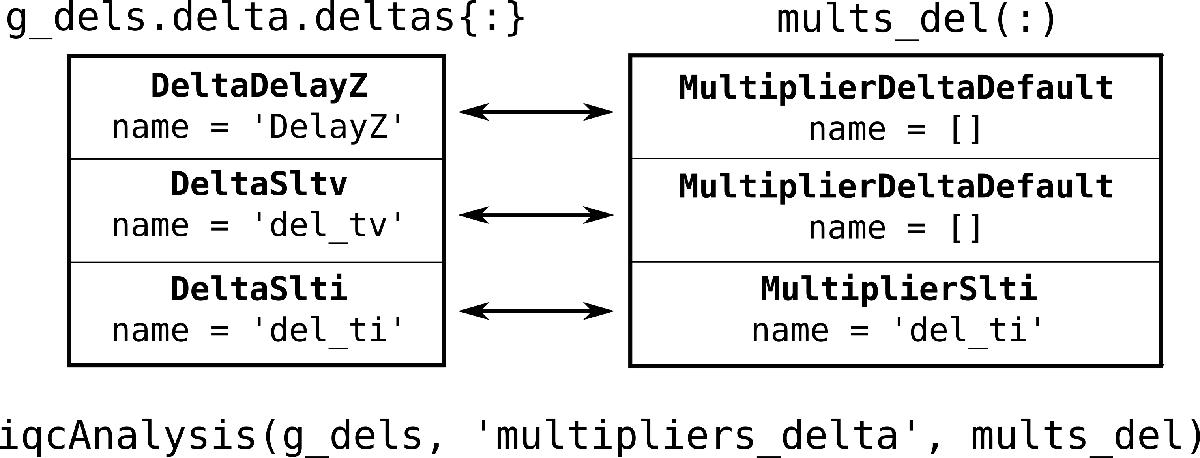

A `MultiplierDeltaDefault` element in the `mults_del` array (such as `mults_del(1)` and `mults_del(2)`) signifies that the multiplier for its associated `Delta` object should be constructed with the multiplier's default constructor arguments. A non-`MultiplierDeltaDefault` element in the `mults_del` array signifies that that specific multiplier should be directly incorporated in IQC analysis.

*NOTE:*

*It may appear odd to users that a (default) multiplier is specified for the *`DeltaDelayZ`* object in the previous example (even though state-evolution operators *`DeltaDelayZ`* and *`DeltaIntegrator`* are not characterized with multipliers). This is necessary to ensure the one-to-one correspondence between the array of *`Delta`* objects in an LFT and the array of *`MultiplierDelta`* objects used when conducting IQC analysis on that LFT.*

If, instead of providing an explicit multiplier for `del_ti`, we wanted to provide one for `del_tv`, we would do the following:

mults_del_another(3) = MultiplierDeltaDefault; % Initialize 3 x 1 array of default multipliers
% Construct a tailored multiplier for del_tv:
m_sltv = MultiplierSltv(g_dels.delta.deltas{2}, 'quad_time_varying', false);
mults_del_another(2) = m_sltv; % Insert tailored multiplier into array of multipliers
results = iqcAnalysis(g_dels, 'multipliers_delta', mults_del_another, 'analysis_options', options)

#### `multipliers_performance`

Following similar syntax for specifying individual multipliers of a `Delta` object, users may provide a specific multiplier for a `Performance` object.  Consider the already discussed system with uncertain initial conditions:


$$G^{ic}_\delta: \quad \quad \matrix{ 
x(k+1) & = & \left[\matrix{ 0 & 3/4 + \delta \cr 3/4 - \delta & 0}\right] & x(k)& + & \left[\matrix{1 \cr 0}\right] & u(k), \qquad ||x(0)|| \leq 1 \cr
y(k) & = & \left[\matrix{1\quad& 0}\right] & x(k)}$$



$$\mbox{ where } \delta \in [-1/2, 1/2]$$


g_del
e_mat = eye(2); % Ellipse specified as {x in R^n | x' * e_mat * x <= 1}
uncertain_states = [true, true];

Though the performance is not explicitly printed, we know that the assumed default performance is `PerformanceL2Induced`:

g_del.performance

We can also specify an explicit `MultiplierPerformance` object for IQC analysis. However, the `MultiplierPerformance` class constructors differ slightly, in that users must also specify the input/output dimensions of the LFT that the multiplier pertains to:

[dim_out, dim_in] = size(g_del);
m_perf = MultiplierL2Induced(g_del.performance.performances{1}, dim_out, dim_in)
options = AnalysisOptions('init_cond_ellipse', e_mat,'init_cond_states', uncertain_states);
result_ic = iqcAnalysis(g_del, 'multipliers_performance', m_perf, 'analysis_options', options)

These results would be equivalent to not specifying any `MultiplierPerformance`, because it was generated without providing additional parameters.  Instead, we can generate a `MultiplierPerformance` whose objective value is scaled differently:

m_perf = MultiplierL2Induced(g_del.performance.performances{1}, dim_out, dim_in,...
                             'objective_scaling', 0);
result_ic = iqcAnalysis(g_del, 'multipliers_performance', m_perf, 'analysis_options', options)

These results are a product of solely optimizing for `state_amplification`, since the `objective_scaling` for the $\ell_2$-induced performance metric is set to `0`. This generates fairly similar values for `state_amplification` as leaving the performance multiplier unspecified (i.e., default) and setting `scale_state_obj` in the `AnalysisOptions` object to be very large.

options = AnalysisOptions('init_cond_ellipse', e_mat,...
                          'init_cond_states', uncertain_states,...
                          'scale_state_obj', 1e8);
result_ic = iqcAnalysis(g_del, 'analysis_options', options)

*Note:*

*Input/output dimensions must be provided when constructing performance multipliers because *`Performance` *objects (as well as *D`isturbance` *objects) pertain to potentially non-contiguous channels. For example, a *`PerformanceL2Induced`* object might pertain to the *`[1, 3]`* input channel and the *`[4] `*output channel of an LFT, rather than all the available input/output channels of the LFT. This additional flexibility in specifying *`Performance`* (and *`Disturbance``)` *objects means users must provide more signal dimension information in constructing the related *`MultiplierPerformance` *(and *`MultiplierDisturbance`*) objects.*

#### `multipliers_disturbance`

Finally, `Disturbance` objects may be specified with explicit `MultiplierDisturbance` objects in IQC analysis. To illustrate this, lets consider $G_\delta$ whose input disturbances are constrained to have constant power spectral density:


$$G_\delta: \quad \quad \matrix{ 
x(k+1) & = & \left[\matrix{ 0 & 3/4 + \delta \cr 3/4 - \delta & 0}\right] & x(k)& + & \left[\matrix{1 \cr 0}\right] & u(k) \cr
y(k) & = & \left[\matrix{1\quad& 0}\right] & x(k)}$$



$$\mbox{ where } \delta \in [-1/2, 1/2]$$


chan_in = {1}; % Indicating the disturbance specification pertains to channel [1]
white = DisturbanceBandedWhite('white', chan_in);
g_del_white = g_del.addDisturbance({white})
result_white = iqcAnalysis(g_del_white);
result_white.performance

Interestingly, without providing a specific multiplier (relying on the default `MultiplierBandedWhite`), we don't get better results than if the disturbance characterization were absent:

result = iqcAnalysis(g_del);
result.performance

We can specify a much larger search space for the `MultiplierBandedWhite` by providing a richer basis function. With a slight variation on the syntax for specifying performance multipliers, disturbance multipliers need users to provide the input dimensions of the associated LFT. Users need not provide the output dimensions of the LFT.

discrete_time = true;
dim_in = size(g_del_white, 2);
basis_poles = linspace(-0.9, 0.9, 8); % Default is basis_poles = -0.5;
m_white = MultiplierBandedWhite(white, dim_in, discrete_time, 'pole', basis_poles)
result_white = iqcAnalysis(g_del_white, 'multipliers_disturbance', m_white)

Because we have a richer set of multipliers to work with, we obtain better results.  This only goes so far though, and having a basis function that is too large will bog down the solver and potentially produce worse results:

basis_poles = linspace(-0.9, 0.9, 100); % Too many poles for computational tractability
m_white = MultiplierBandedWhite(white, dim_in, discrete_time, 'pole', basis_poles);
% Following command commented out to prevent clogging up your computer
% result_white = iqcAnalysis(g_del_white, 'multipliers_disturbance', m_white)

The "right balance" between expressiveness and tractability is specific to an individual's workstation and the solvers they have available. Hence the need for users to individually specify characteristics of each multiplier.

### Exponential IQCs

An explanation of this parameter is found in the dedicated documentation "Exponential IQCs"

## Output arguments from `iqcAnalysis`

As of v0.9.0, `iqcAnalysis` outputs 4 arguments: `result`, `valid`, `yalmip_report`, and `lft_analyzed`.

### `result`

This variable contains information on the results of conducting IQC analysis.

#### `performance` and `valid`

`result.performance` is the objective value for the LFT's `Performance` object. The meaning of this value differs for each `Performance` object.  For example, if a `Ulft` object had a `PerformanceL2Induced` object, than `result.performance` represents the $\gamma$-value for Equation $(4)$, restated below:


$$(4) \qquad ||e||^2_{\ell_2} < \gamma^2 ||d||^2_{\ell_2} + \lambda^2\mbox{ where } e = (M^{ic}, \Delta)(d), \ \Delta \in \Delta_\mbox{set}, \ d \in \mathcal{D} \subseteq \ell_2, \ x_M(0) \in E(\Xi)$$


However, if using `PerformancePassive`, `result.performance = 0` signifies that the system is robustly strictly input passive.

In all cases, if `result.performance = Inf`, then the solver did not return a feasible solution.  Sometimes this is not because the problem is infeasible, but merely because the solution only slightly violates the given constraints.  This issue can be diagnosed by inspecting the solver output (did it report converging to a reasonable value?) and the problem's constraints (`check(result.debug.constraints)`, are all the values primal residuals positive?). This issue can usually be fixed by setting larger shift margins for strict LMI constraints (`AnalysisOptions('lmi_shift', 1e-6)`). 

If users suspect that `result.performance = Inf` because of small violations in the constraints (rather than the problem being truly infeasible), than a quick workaround to getting the resulting `performance` value is evaluating the `objective` of the `result.multipliers_performance`:

value(result.multipliers_performance(1).objective)

`result.valid` is a logical value stating whether the returned solution satisfies all it's constraint. It is `false` if and only if `result.performance = Inf`.

#### `state_amplification` and `ellipse`

These variables are already discussed in the "Uncertain Initial Conditions" subsection of this documentation. In short, `state_amplification` expresses the $\lambda$-value in Equation$(3)$(restated below) for systems with uncertain initial conditions, and `ellipse` expresses the positive definite matrix $\Xi$ specifying the ellipse $E(\Xi)$ in which any admissible initial condition may reside.


$$(3) \qquad \langle \left[\matrix{e \cr d}\right], \Pi_P \left[\matrix{e \cr d}\right]\rangle < \lambda^2\mbox{ where } e = (M^{ic}, \Delta)(d), \ \Delta \in \Delta_\mbox{set}, \ d \in \mathcal{D} \subseteq \ell_2, \ x_M(0) \in E(\Xi) = \{x\in\mathbb{R}^n | \ x^T \Xi x \leq 1\}$$


#### `multipliers_delta`, `multipliers_disturbance`, and `multipliers_performance`

These variables express the multipliers characterizing `Delta`, `Disturbance`, and `Performance` objects ($\Pi_\Delta$, $\Pi_D$, and $\Pi_P$). Whereas multipliers could have been supplied as inputs, the output multipliers now have values associated with their decision variables.  For example:

m_white.decision_vars{1}
result_white.multipliers_disturbance(1).decision_vars{1}

Their constraints may also be checked:

check(result.multipliers_delta(2).constraints)

#### `multiplier_combined`

This variable reflects a specially structure concatentation of all the multipliers expressing `Delta`, `Disturbance`, and `Performance` objects ( $\Pi_{all} = \mathrm{Augment}(\Pi_\Delta, \Pi_D, \Pi_P)$) and is used to formulate the semidefinite program in `iqcAnalysis`.  `result.multiplier_combined` contains all the decision variables and constraints of every multiplier used in IQC analysis. It is usually used for debugging purposes.

#### `kyp_variables`

This variable contains the (oftentime indefinite) $P$ solution matrix to the KYP-derived IQC analysis problem. If the `Ulft` object is `[h, p`]-eventually periodic, then there are `h + p + 1` matrices in `kyp_variables`.  The first `h + p` matrices are `P(1)` to `P(h + p)`. The last matrix `P(end)` represents a projection of `P(1)` pertaining to the uncertain initial states of the LFT.  If the initial state is exactly zero (i.e., no uncertain initial conditions), then `kyp_variables{end} == kyp_variables{1}`

% No uncertain initial conditions:
value(result.kyp_variables{1})
value(result.kyp_variables{end})
% Uncertain initial conditions:
p0 = value(result_ic.kyp_variables{1});
psi_states = false(1, size(result_ic.multiplier_combined.filter.a{1}, 1));
states = [psi_states, uncertain_states];
p0_uncertain_states = p0(states, states)
value(result_ic.kyp_variables{end})

#### `exponential`

Discussed in the "Exponential IQCs" documentation

#### `debug`

This contains additional information on the solution to the semidefinite program. `result.debug.constraints` shows all the constraints used in the semidefinite program. `result.debug.yalmip_report` provides the print out from the problem parsing toolbox YALMIP, which helps indicate if there were issues (interfacing, feasibility, etc.) with the solvers.

### `valid` and `yalmip_report`

These two output variables are provided for convenience access, as they are duplicates of `result.valid` and `result.debug.yalmip_report`

### `lft_analyzed`

This final output provides the actual LFT that was used in analysis.  This LFT differs from the input LFT when certain `Delta`, `Disturbance`, or `Performance` objects specify that the input LFT must be modified to conduct analysis.  For example, consider the system:


$$G_\delta: \quad \quad \matrix{ 
x(k+1) & = & \left[\matrix{ 0 & 3/4 + \delta(k) \cr 3/4 - \delta(k) & 0}\right] & x(k)& + & \left[\matrix{1 \cr 0}\right] & u(k) \cr
y(k) & = & \left[\matrix{1\quad& 0}\right] & x(k)}$$



$$\mbox{ where } \delta(k) \in [-1/2, \ 1/2], \ \ \delta(k+1) - \delta(k) \in [-1/4, \ 1/4]
$$


lower_rate = -1/4;
upper_rate = 1/4;
del_rb = DeltaSltvRateBnd('del_rb', dims, lower_bound, upper_bound, lower_rate, upper_rate)
a_rb = [0,            3/4 + del_rb;
        3/4 - del_rb,            0];
g_del_rb = toLft(a_rb, b, c, d, timestep)

This LFT is robustly stable if and only if a modified LFT (with a modified uncertainty operator) is robustly stable (see [1]). This can be seen by inspecting the fourth output argument of `iqcAnalysis`:

[result_rb, ~, ~, lft_rb] = iqcAnalysis(g_del_rb);
lft_rb
compareObjects(g_del_rb, lft_rb)

The same can be seen when analyzing the LFT with the `PerformanceStable` object (i.e., only checking for robust stability):

[result_rb_stable, ~, ~, lft_rb_stable] = iqcAnalysis(addPerformance(g_del_rb,...
                                                                     {PerformanceStable}));
lft_rb_stable
compareObjects(lft_rb, lft_rb_stable)

## Conclusion

Congrats for learning the core capabilities of `iqcAnalysis`, the central function in `iqcToolbox`! You should now know the basic meaning of the results obtained from `iqcAnalysis `and how to specify additional arguments to better tailor your robustness analysis problem. You may also be interested in reading about exponential IQCs, a recent feature in the toolbox implementing theoretical contributions that are useful for verifying optimization algorithms [2], developing robust MPC control laws [3], synthesizing robust RNN controllers [4], and more. If you're interested in developing additional features to this toolbox, consider exploring the developer documentation as well. 

## References

[1] Koroglu, H., & Scherer, C. W.  (2007). Robust performance analysis for structured linear time-varying  perturbations with bounded rates-of-variation. *IEEE Transactions on Automatic Control*, *52*(2), 197-211.

[2] Lessard, L., Recht, B., & Packard, A. (2016). Analysis and design of optimization algorithms via integral  quadratic constraints. *SIAM Journal on Optimization*, *26*(1), 57-95.

[3] Schwenkel, L., Köhler, J., Müller, M.  A., & Allgöwer, F. (2021). Model predictive control for linear  uncertain systems using integral quadratic constraints. *arXiv preprint arXiv:2104.05444*.

[4] Gu, F., Yin, H., Ghaoui, L. E., Arcak, M., Seiler, P., & Jin, M. (2021). Recurrent neural network  controllers synthesis with stability guarantees for partially observed  systems. *arXiv preprint arXiv:2109.03861*.